## 姿勢計算50本ノック

## 1-04 適当な平均と標準偏差を持つ2次元ガウス分布を3次元空間にプロットせよ．

clc
clear
close all

## plotするx,yの範囲指定

xySpan = -3:0.1:3;
[x, y] = meshgrid(xySpan, xySpan); % meshgrid使うのが楽


### covariance matrix

sig = [0.25 0.3
    0.3  1];
sigInv = sig^(-1);


### mean vector

mu = [0
    0];

% 計算のために
X = x - mu(1);
Y = y - mu(2);

% 2次形式なので展開したものを計算．もっと上手い方法あるはず．．．
z = 1 / (2*pi) / sqrt(det(sig)) ...
   .* exp(-0.5 .* (sigInv(1,1) .* X.^2 + 2 * sigInv(1,2) .* X .* Y + sigInv(2,2) .* Y.^2));

## plot

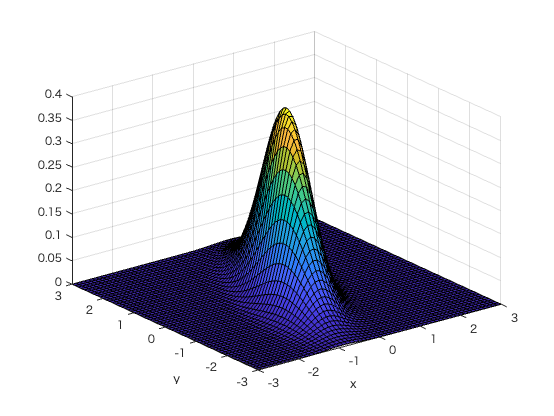

figure
surf(x, y, z) % surfを使うのが自然かな
xlabel('x'), ylabel('y')